# **Proof of Concept**

**Notes: **It needs Yalmip and OSQP. Yalmip should install himself automatically both on Windows and Linux. OSQP should automatically install on Linux, if there are any problems read the README. On Windows you need to install OSQP yourself.

There are TONs of other parameters and configuration you can tune and adapt, but atm you need to search them yourself.

clc;
clear variables;
terminate(pyenv)
%pyenv(Version='/scratch/msc23h12/python/bin/python3',ExecutionMode='OutOfProcess');

## **Initialization**

%% INIT

% Instantiate main Class:
hpc = hpc_lab;

MAY be NOT Observable!
Size: 54800 bytes



% Core number
hpc.Nc = 9;

[TM] Remember to change Nh, Nv, epos, the parameter deviation vector, and the floorplan accordingly



% Rows and Columns
hpc.Nv = 3;

[TM] Remember to change Nh, epos, and the floorplan accordingly


hpc.Nh = 3;

[TM] Remember to change Nv, epos, and the floorplan accordingly



% Number of Voltage Domains
hpc.vd = 3;

% How the cores are distributed per domain
%hpc.VDom = ... ;
% Alternatively
hpc.default_VDom_config();

% Default Floorplan and Parameter deviation vector
hpc.default_floorplan_config();
hpc.create_model_deviation();

%Decide simulation frequency (discrete timing)
hpc.Ts = 5e-5;

%Decide total simulation time
hpc.tsim = 2;

%Presence/Absence of sensor noise:
hpc.sensor_noise = 1;

%Thermal model version
hpc.model_ver = 0;

#### After the configuration of the Thermal Model, run the model creation & others

hpc.model_init();

MAY be NOT Observable!


hpc.create_core_pw_noise();

#### Choose targets

% Initial Temperature condition
hpc.t_init = hpc.temp_amb*ones(hpc.Ns,1);

%Input maximum frequency
hpc.Ts_target;

tt = min(ceil(hpc.tsim / hpc.Ts_target)+1, (hpc.tsim/1e-4+1));

% Target Frequency Trajectory
hpc.frtrc = 3.45 * ones(tt, hpc.Nc);

%Target Power Budget
hpc.tot_pw_budget = 450/36*hpc.Nc*ones(tt,1);
tu = ceil(tt/4);
hpc.tot_pw_budget(tu+1:2*tu) = 2*hpc.Nc;
hpc.tot_pw_budget(2*tu+1:3*tu) = 5*hpc.Nc;
hpc.tot_pw_budget(3*tu+1:3*tu+ceil(tu/2)) = 3*hpc.Nc;
hpc.tot_pw_budget(3*tu+ceil(tu/2)+1:end) = 8*hpc.Nc;
hpc.quad_pw_budget = 450/36*hpc.Nc*ones(2,hpc.vd);

%Others, TODO
hpc.min_pw_red = 0.6;

#### After all the configurations are done, running the checks:

hpc.anteSimCheckTM();
hpc.anteSimCheckLab();
hpc.anteSimCheckPM();

### **Generate Workload trace:**

%Probability of each workload type [idle, int, float, mem, vec]
hpc.wl_prob = [0.0345 0.3448 0.3448 0.2414 0.0345];

%Minimum execution time (us) of each workload type
hpc.wl_min_exec_us = [510 100 100 480 520];	

%Mean execution time (us) of each workload type
hpc.wl_mean_exec_us = [520e2 210e1 180e1 560e2 1.2e6/1e1];

%Generate it
hpc.wltrc = hpc.generate_wl_trace(hpc.Nc, hpc.tsim, 0);


## **SotA / CP MPC - no warm starting**

ctrl = cp_mpc;

Unpacking...					[done]
Updating path...

				[done]
Deleting temporary files...			[done]
OSQP is successfully installed!


ctrl.save_solver_stats = true;
ctrl.C = eye(hpc.Ns);

%Controller frequency (s)
trl.Ts_ctrl = 5e-3;
ctrl.Nhzn = 2;

%Robust Margins for T and P
ctrl.Cty = zeros(ctrl.Nhzn, hpc.Nc);
ctrl.Ctu = zeros(ctrl.Nhzn, hpc.Nc);

%Reference Tracking Objective Matrix
R_coeff = 10;
ctrl.R = R_coeff*eye(hpc.Nc);

%Others
ctrl.R2 = zeros(hpc.Nc);
ctrl.Q = zeros(hpc.Ns);

Optimizer object with 33 inputs (4 blocks) and 31 outputs (2 blocks). Solver: OSQP


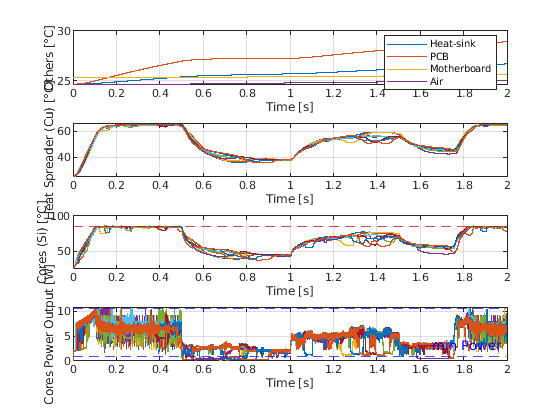

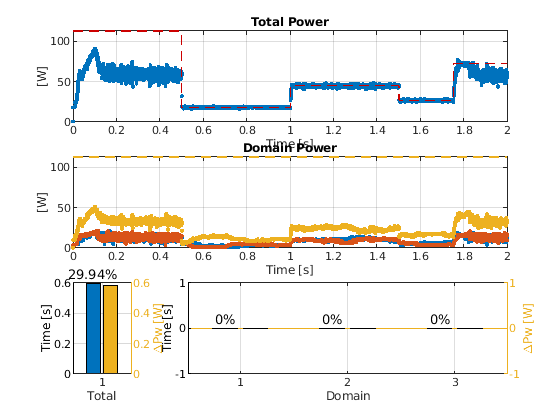

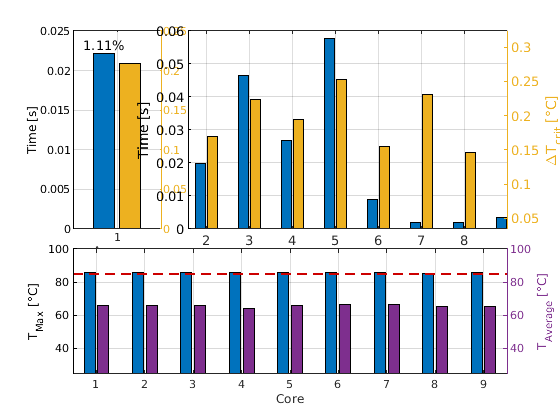

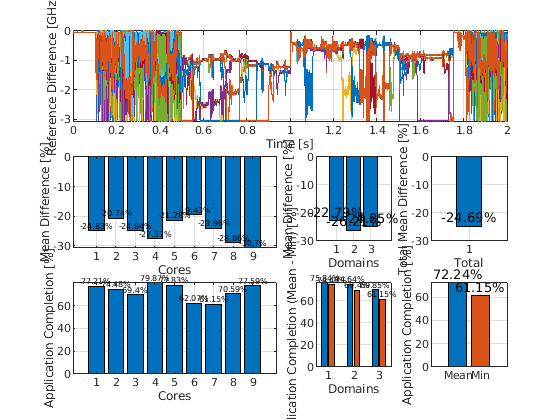

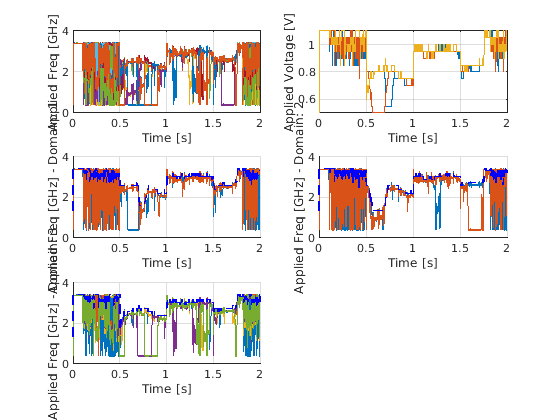

[CTRL][MPC] number of times the optimization algorithm failed:0/4000


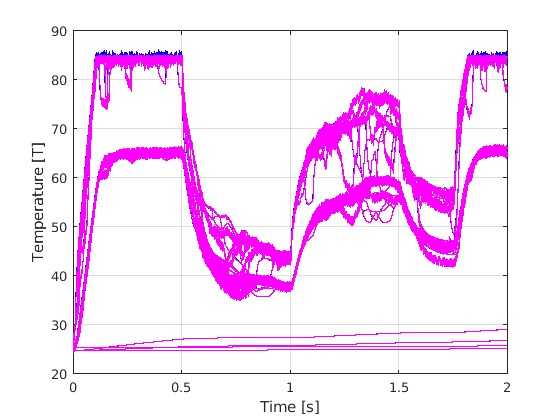

%Launch Simulation
tic;
hpc.simulation(ctrl,1);

toc;

Elapsed time is 36.475043 seconds.


## Warm Starting

ctrl = cp_mpc;
set = osqp.default_settings;
set.warm_start = true;
set.verbose = true;
set.rho = 0.04; %0.1
set.eps_abs = 0.01; %0.01
set.eps_rel = 0.0001; %0.01
set.check_termination = 0;
set.max_iter = 7;
ctrl.ops = set;
            %ops.osqp.max_iter = 17;

ctrl.save_solver_stats = true; 
ctrl.C = eye(hpc.Ns);

%Controller frequency (s)
trl.Ts_ctrl = 5e-3;
ctrl.Nhzn = 2;

%Robust Margins for T and P
ctrl.Cty = zeros(ctrl.Nhzn, hpc.Nc);
ctrl.Ctu = zeros(ctrl.Nhzn, hpc.Nc);

%Reference Tracking Objective Matrix
R_coeff = 10;
ctrl.R = R_coeff*eye(hpc.Nc);

%Others
ctrl.R2 = zeros(hpc.Nc);
ctrl.Q = zeros(hpc.Ns);

ans = struct with fields:
                       rho: 0.0400
                     sigma: 1.0000e-06
                   scaling: 10
              adaptive_rho: 1
     adaptive_rho_interval: 0
    adaptive_rho_tolerance: 5
     adaptive_rho_fraction: 0.4000
                  max_iter: 7
                   eps_abs: 0.0100
                   eps_rel: 1.0000e-04
              eps_prim_inf: 1.0000e-04
              eps_dual_inf: 1.0000e-04
                     alpha: 1.6000
             linsys_solver: 'qdldl'
                     delta: 1.0000e-06
                    polish: 0
        polish_refine_iter: 3
                   verbose: 1
        scaled_termination: 0
         check_termination: 0
                warm_start: 1
                time_limit: 0


-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 95, constraints m = 97
          nnz(P) + nnz(A) = 1568
settings: linear system solver = qdldl,
          eps_abs = 1.0e-02, eps_rel = 1.0e-04,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 4.00e-02 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 7
          check_termination: off,
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off

iter   objective    pri res    dua res    rho        time
   1   0.0000e+00   2.98e+05   1.19e+07   4.00e-02   4.34e-04s
   7   2.2401e+01   2.36e+05   5.56e+05   4.00e-02   7.62e-04s

status:               maximum iterations reached
number of it

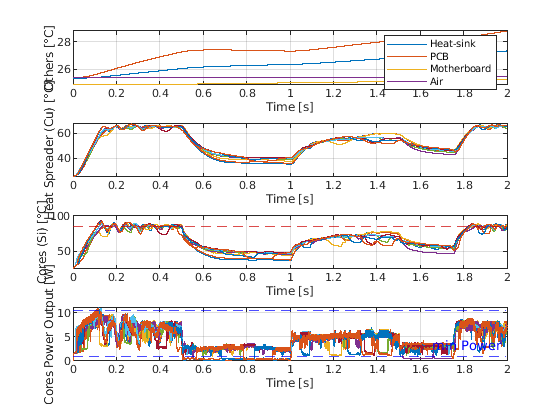

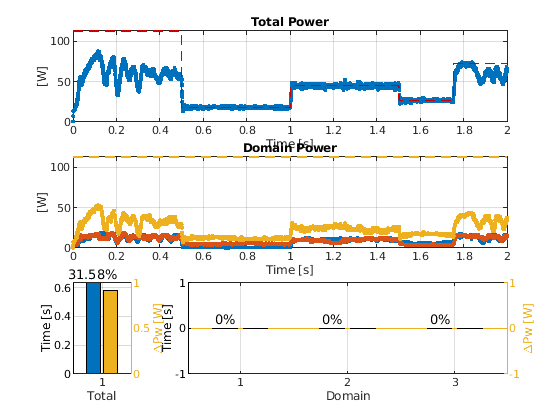

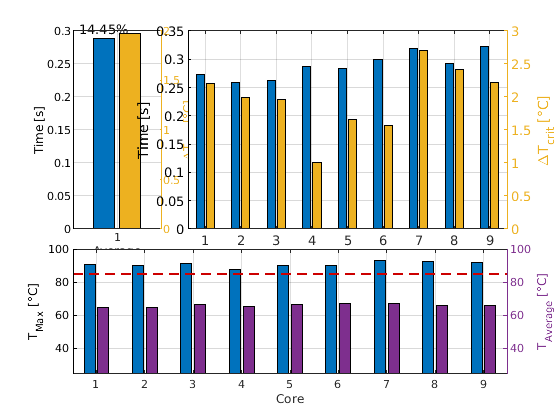

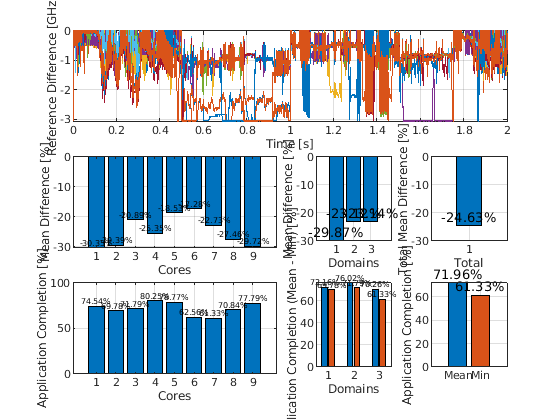

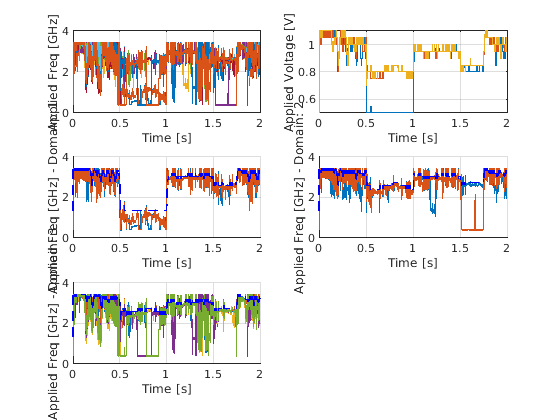

[CTRL][MPC] number of times the optimization algorithm failed:0/4000


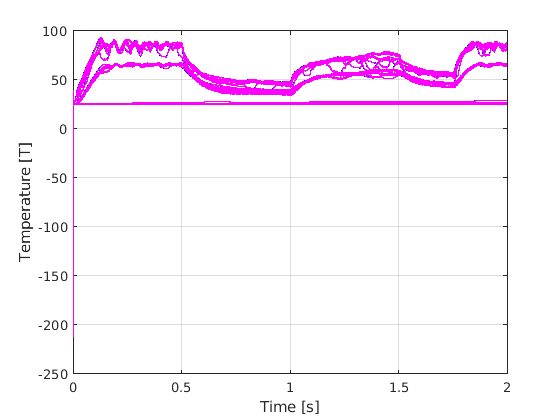

ans =   298.5441  298.2056  298.0186  297.8136  298.1003  298.3915  298.6256  297.7775  298.5217  297.9479  298.4535  297.7612  297.9122  298.3744  298.5692  297.8026  297.7401  298.3544  298.4766  298.5375  297.9761  298.5577
  298.5427  298.2053  298.0198  297.8163  298.1034  298.3899  298.6210  297.7803  298.5196  297.9483  298.4503  297.7637  297.9173  298.3723  298.5641  297.8066  297.7463  298.3522  298.4765  298.5375  297.9761  298.5576
  298.5412  298.2049  298.0209  297.8190  298.1064  298.3882  298.6165  297.7831  298.5175  297.9488  298.4471  297.7661  297.9223  298.3702  298.5590  297.8105  297.7524  298.3500  298.4765  298.5374  297.9761  298.5576
  298.5398  298.2046  298.0221  297.8217  298.1094  298.3865  298.6121  297.7859  298.5154  297.9493  298.4439  297.7686  297.9273  298.3681  298.5540  297.8145  297.7584  298.3478  298.4765  298.5374  297.9761  298.5576
  298.5385  298.2043  298.0233  297.8244  298.1124  298.3849  298.6078  297.7887  298.5133  297.9498  298.4408


%Launch Simulation
tic;
hpc.simulation(ctrl,1)

toc;

Elapsed time is 40.726344 seconds.


## Run Checks and Optain Metrics

% get primal variables from optimizer
prim = [ctrl.solver_stats.prim];
dual = [ctrl.solver_stats.dua];

pusum = prim(end,:);

u0ap = [ctrl.solver_stats.u0];
usum = [ctrl.solver_stats.usum];
uref = [ctrl.solver_stats.uref];
info = [ctrl.solver_stats.info];
lin  = [ctrl.solver_stats.lin];
uin  = [ctrl.solver_stats.uin];
iter = [info.iter];

% average rho estimate
rho_estimate = [info.rho_estimate];
mean(rho_estimate)

ans = 1.6952e-04

min(rho_estimate)

ans = 6.2324e-05

max(rho_estimate)

ans = 0.0356

mean(iter)

ans = 7

min(iter)

ans = 7

max(iter)

ans = 7


% check constraints row by row
for i= 1:length(ctrl.mz.A)
    fprintf('row: %i: ',i);
    disp(ctrl.mz.A(i,:)); %display each row
end

row: 1: 

   (1,1)        1



row: 2: 

   (1,2)        1



row: 3: 

   (1,3)        1



row: 4: 

   (1,4)        1



row: 5: 

   (1,5)        1



row: 6: 

   (1,6)        1



row: 7: 

   (1,7)        1



row: 8: 

   (1,8)        1



row: 9: 

   (1,9)        1



row: 10: 

   (1,10)       1



row: 11: 

   (1,11)       1



row: 12: 

   (1,12)       1



row: 13: 

   (1,13)       1



row: 14: 

   (1,14)       1



row: 15: 

   (1,15)       1



row: 16: 

   (1,16)       1



row: 17: 

   (1,17)       1



row: 18: 

   (1,18)       1



row: 19: 

   (1,19)       1



row: 20: 

   (1,20)       1



row: 21: 

   (1,21)       1



row: 22: 

   (1,22)       1



row: 23: 

   (1,85)       1



row: 24: 

   (1,86)       1



row: 25: 

   (1,87)       1



row: 26: 

   (1,88)       1



row: 27: 

   (1,89)       1



row: 28: 

   (1,90)       1



row: 29: 

   (1,91)       1



row: 30: 

   (1,92)       1



row: 31: 

   (1,93)       1



row: 32: 

   (1,94)       1



row: 33: 

   (1,95)       1



row: 34: 

   (1,1)      -0.4795
   (1,2)      -0.3278
   (1,3)      -0.0615
   (1,4)      -0.0532
   (1,5)      -0.0038
   (1,6)      -0.0043
   (1,7)      -0.0145
   (1,8)      -0.0130
   (1,9)      -0.0019
   (1,10)     -0.0021
   (1,11)     -0.0001
   (1,12)     -0.0002
   (1,13)     -0.0003
   (1,14)     -0.0003
   (1,15)     -0.0000
   (1,16)     -0.0000
   (1,17)     -0.0000
   (1,18)     -0.0000
   (1,19)     -0.0160
   (1,20)     -0.0213
   (1,21)     -0.0000
   (1,22)     -0.0000
   (1,23)      1.0000
   (1,67)     -1.4232
   (1,68)     -0.0819
   (1,69)     -0.0031
   (1,70)     -0.0190
   (1,71)     -0.0015
   (1,72)     -0.0001
   (1,73)     -0.0002
   (1,74)     -0.0000
   (1,75)     -0.0000
   (1,85)     -0.0000



row: 35: 

   (1,1)      -0.0812
   (1,2)      -0.6597
   (1,3)      -0.0132
   (1,4)      -0.1255
   (1,5)      -0.0011
   (1,6)      -0.0121
   (1,7)      -0.0032
   (1,8)      -0.0306
   (1,9)      -0.0005
   (1,10)     -0.0058
   (1,11)     -0.0000
   (1,12)     -0.0006
   (1,13)     -0.0001
   (1,14)     -0.0008
   (1,15)     -0.0000
   (1,16)     -0.0002
   (1,17)     -0.0000
   (1,18)     -0.0000
   (1,19)     -0.0637
   (1,20)     -0.0016
   (1,21)     -0.0000
   (1,22)     -0.0000
   (1,24)      1.0000
   (1,67)     -0.1011
   (1,68)     -0.0107
   (1,69)     -0.0006
   (1,70)     -0.0026
   (1,71)     -0.0003
   (1,72)     -0.0000
   (1,73)     -0.0000
   (1,74)     -0.0000
   (1,75)     -0.0000
   (1,85)     -0.0000



row: 36: 

   (1,1)      -0.0633
   (1,2)      -0.0549
   (1,3)      -0.4224
   (1,4)      -0.2864
   (1,5)      -0.0548
   (1,6)      -0.0477
   (1,7)      -0.0019
   (1,8)      -0.0022
   (1,9)      -0.0128
   (1,10)     -0.0113
   (1,11)     -0.0017
   (1,12)     -0.0019
   (1,13)     -0.0000
   (1,14)     -0.0001
   (1,15)     -0.0002
   (1,16)     -0.0003
   (1,17)     -0.0000
   (1,18)     -0.0000
   (1,19)     -0.0165
   (1,20)     -0.0215
   (1,21)     -0.0000
   (1,22)     -0.0000
   (1,25)      1.0000
   (1,67)     -0.0843
   (1,68)     -1.3450
   (1,69)     -0.0727
   (1,70)     -0.0016
   (1,71)     -0.0176
   (1,72)     -0.0014
   (1,73)     -0.0000
   (1,74)     -0.0002
   (1,75)     -0.0000
   (1,85)     -0.0000



row: 37: 

   (1,1)      -0.0136
   (1,2)      -0.1291
   (1,3)      -0.0710
   (1,4)      -0.5540
   (1,5)      -0.0118
   (1,6)      -0.1124
   (1,7)      -0.0006
   (1,8)      -0.0060
   (1,9)      -0.0028
   (1,10)     -0.0257
   (1,11)     -0.0005
   (1,12)     -0.0052
   (1,13)     -0.0000
   (1,14)     -0.0002
   (1,15)     -0.0001
   (1,16)     -0.0007
   (1,17)     -0.0000
   (1,18)     -0.0001
   (1,19)     -0.0647
   (1,20)     -0.0016
   (1,21)     -0.0000
   (1,22)     -0.0000
   (1,26)      1.0000
   (1,67)     -0.0109
   (1,68)     -0.0933
   (1,69)     -0.0094
   (1,70)     -0.0003
   (1,71)     -0.0023
   (1,72)     -0.0003
   (1,73)     -0.0000
   (1,74)     -0.0000
   (1,75)     -0.0000
   (1,85)     -0.0000



row: 38: 

   (1,1)      -0.0038
   (1,2)      -0.0043
   (1,3)      -0.0533
   (1,4)      -0.0462
   (1,5)      -0.4878
   (1,6)      -0.3348
   (1,7)      -0.0001
   (1,8)      -0.0002
   (1,9)      -0.0016
   (1,10)     -0.0019
   (1,11)     -0.0148
   (1,12)     -0.0133
   (1,13)     -0.0000
   (1,14)     -0.0000
   (1,15)     -0.0000
   (1,16)     -0.0000
   (1,17)     -0.0003
   (1,18)     -0.0003
   (1,19)     -0.0160
   (1,20)     -0.0213
   (1,21)     -0.0000
   (1,22)     -0.0000
   (1,27)      1.0000
   (1,67)     -0.0031
   (1,68)     -0.0707
   (1,69)     -1.4345
   (1,70)     -0.0001
   (1,71)     -0.0013
   (1,72)     -0.0192
   (1,73)     -0.0000
   (1,74)     -0.0000
   (1,75)     -0.0002
   (1,85)     -0.0000



row: 39: 

   (1,1)      -0.0011
   (1,2)      -0.0121
   (1,3)      -0.0115
   (1,4)      -0.1093
   (1,5)      -0.0830
   (1,6)      -0.6760
   (1,7)      -0.0000
   (1,8)      -0.0006
   (1,9)      -0.0005
   (1,10)     -0.0051
   (1,11)     -0.0033
   (1,12)     -0.0314
   (1,13)     -0.0000
   (1,14)     -0.0000
   (1,15)     -0.0000
   (1,16)     -0.0001
   (1,17)     -0.0001
   (1,18)     -0.0008
   (1,19)     -0.0636
   (1,20)     -0.0016
   (1,21)     -0.0000
   (1,22)     -0.0000
   (1,28)      1.0000
   (1,67)     -0.0006
   (1,68)     -0.0092
   (1,69)     -0.1026
   (1,70)     -0.0000
   (1,71)     -0.0003
   (1,72)     -0.0026
   (1,73)     -0.0000
   (1,74)     -0.0000
   (1,75)     -0.0000
   (1,85)     -0.0000



row: 40: 

   (1,1)      -0.0158
   (1,2)      -0.0143
   (1,3)      -0.0020
   (1,4)      -0.0024
   (1,5)      -0.0001
   (1,6)      -0.0002
   (1,7)      -0.4484
   (1,8)      -0.3238
   (1,9)      -0.0576
   (1,10)     -0.0526
   (1,11)     -0.0036
   (1,12)     -0.0043
   (1,13)     -0.0158
   (1,14)     -0.0143
   (1,15)     -0.0020
   (1,16)     -0.0024
   (1,17)     -0.0001
   (1,18)     -0.0002
   (1,19)     -0.0179
   (1,20)     -0.0221
   (1,21)     -0.0001
   (1,22)     -0.0000
   (1,29)      1.0000
   (1,67)     -0.0208
   (1,68)     -0.0017
   (1,69)     -0.0001
   (1,70)     -1.3807
   (1,71)     -0.0785
   (1,72)     -0.0030
   (1,73)     -0.0208
   (1,74)     -0.0017
   (1,75)     -0.0001
   (1,85)     -0.0000



row: 41: 

   (1,1)      -0.0035
   (1,2)      -0.0334
   (1,3)      -0.0006
   (1,4)      -0.0064
   (1,5)      -0.0000
   (1,6)      -0.0006
   (1,7)      -0.0802
   (1,8)      -0.6181
   (1,9)      -0.0131
   (1,10)     -0.1175
   (1,11)     -0.0011
   (1,12)     -0.0113
   (1,13)     -0.0035
   (1,14)     -0.0334
   (1,15)     -0.0006
   (1,16)     -0.0064
   (1,17)     -0.0000
   (1,18)     -0.0006
   (1,19)     -0.0679
   (1,20)     -0.0018
   (1,21)     -0.0000
   (1,22)     -0.0000
   (1,30)      1.0000
   (1,67)     -0.0028
   (1,68)     -0.0003
   (1,69)     -0.0000
   (1,70)     -0.1025
   (1,71)     -0.0107
   (1,72)     -0.0006
   (1,73)     -0.0028
   (1,74)     -0.0003
   (1,75)     -0.0000
   (1,85)     -0.0000



row: 42: 

   (1,1)      -0.0021
   (1,2)      -0.0024
   (1,3)      -0.0139
   (1,4)      -0.0125
   (1,5)      -0.0018
   (1,6)      -0.0021
   (1,7)      -0.0592
   (1,8)      -0.0542
   (1,9)      -0.3949
   (1,10)     -0.2827
   (1,11)     -0.0513
   (1,12)     -0.0471
   (1,13)     -0.0021
   (1,14)     -0.0024
   (1,15)     -0.0139
   (1,16)     -0.0125
   (1,17)     -0.0018
   (1,18)     -0.0021
   (1,19)     -0.0184
   (1,20)     -0.0224
   (1,21)     -0.0001
   (1,22)     -0.0000
   (1,31)      1.0000
   (1,67)     -0.0017
   (1,68)     -0.0192
   (1,69)     -0.0015
   (1,70)     -0.0808
   (1,71)     -1.3055
   (1,72)     -0.0697
   (1,73)     -0.0017
   (1,74)     -0.0192
   (1,75)     -0.0015
   (1,85)     -0.0000



row: 43: 

   (1,1)      -0.0006
   (1,2)      -0.0065
   (1,3)      -0.0031
   (1,4)      -0.0280
   (1,5)      -0.0005
   (1,6)      -0.0057
   (1,7)      -0.0134
   (1,8)      -0.1209
   (1,9)      -0.0700
   (1,10)     -0.5191
   (1,11)     -0.0116
   (1,12)     -0.1052
   (1,13)     -0.0006
   (1,14)     -0.0065
   (1,15)     -0.0031
   (1,16)     -0.0280
   (1,17)     -0.0005
   (1,18)     -0.0057
   (1,19)     -0.0690
   (1,20)     -0.0018
   (1,21)     -0.0000
   (1,22)     -0.0000
   (1,32)      1.0000
   (1,67)     -0.0003
   (1,68)     -0.0025
   (1,69)     -0.0003
   (1,70)     -0.0110
   (1,71)     -0.0945
   (1,72)     -0.0095
   (1,73)     -0.0003
   (1,74)     -0.0025
   (1,75)     -0.0003
   (1,85)     -0.0000



row: 44: 

   (1,1)      -0.0001
   (1,2)      -0.0002
   (1,3)      -0.0018
   (1,4)      -0.0020
   (1,5)      -0.0161
   (1,6)      -0.0146
   (1,7)      -0.0036
   (1,8)      -0.0043
   (1,9)      -0.0499
   (1,10)     -0.0456
   (1,11)     -0.4562
   (1,12)     -0.3307
   (1,13)     -0.0001
   (1,14)     -0.0002
   (1,15)     -0.0018
   (1,16)     -0.0020
   (1,17)     -0.0161
   (1,18)     -0.0146
   (1,19)     -0.0179
   (1,20)     -0.0221
   (1,21)     -0.0001
   (1,22)     -0.0000
   (1,33)      1.0000
   (1,67)     -0.0001
   (1,68)     -0.0015
   (1,69)     -0.0210
   (1,70)     -0.0030
   (1,71)     -0.0677
   (1,72)     -1.3915
   (1,73)     -0.0001
   (1,74)     -0.0015
   (1,75)     -0.0210
   (1,85)     -0.0000



row: 45: 

   (1,1)      -0.0000
   (1,2)      -0.0006
   (1,3)      -0.0005
   (1,4)      -0.0055
   (1,5)      -0.0036
   (1,6)      -0.0342
   (1,7)      -0.0011
   (1,8)      -0.0113
   (1,9)      -0.0113
   (1,10)     -0.1023
   (1,11)     -0.0819
   (1,12)     -0.6333
   (1,13)     -0.0000
   (1,14)     -0.0006
   (1,15)     -0.0005
   (1,16)     -0.0055
   (1,17)     -0.0036
   (1,18)     -0.0342
   (1,19)     -0.0679
   (1,20)     -0.0018
   (1,21)     -0.0000
   (1,22)     -0.0000
   (1,34)      1.0000
   (1,67)     -0.0000
   (1,68)     -0.0003
   (1,69)     -0.0028
   (1,70)     -0.0006
   (1,71)     -0.0093
   (1,72)     -0.1039
   (1,73)     -0.0000
   (1,74)     -0.0003
   (1,75)     -0.0028
   (1,85)     -0.0000



row: 46: 

   (1,1)      -0.0003
   (1,2)      -0.0003
   (1,3)      -0.0000
   (1,4)      -0.0000
   (1,5)      -0.0000
   (1,6)      -0.0000
   (1,7)      -0.0145
   (1,8)      -0.0130
   (1,9)      -0.0019
   (1,10)     -0.0021
   (1,11)     -0.0001
   (1,12)     -0.0002
   (1,13)     -0.4795
   (1,14)     -0.3278
   (1,15)     -0.0615
   (1,16)     -0.0532
   (1,17)     -0.0038
   (1,18)     -0.0043
   (1,19)     -0.0160
   (1,20)     -0.0213
   (1,21)     -0.0000
   (1,22)     -0.0000
   (1,35)      1.0000
   (1,67)     -0.0002
   (1,68)     -0.0000
   (1,69)     -0.0000
   (1,70)     -0.0190
   (1,71)     -0.0015
   (1,72)     -0.0001
   (1,73)     -1.4232
   (1,74)     -0.0819
   (1,75)     -0.0031
   (1,85)     -0.0000



row: 47: 

   (1,1)      -0.0001
   (1,2)      -0.0008
   (1,3)      -0.0000
   (1,4)      -0.0002
   (1,5)      -0.0000
   (1,6)      -0.0000
   (1,7)      -0.0032
   (1,8)      -0.0306
   (1,9)      -0.0005
   (1,10)     -0.0058
   (1,11)     -0.0000
   (1,12)     -0.0006
   (1,13)     -0.0812
   (1,14)     -0.6597
   (1,15)     -0.0132
   (1,16)     -0.1255
   (1,17)     -0.0011
   (1,18)     -0.0121
   (1,19)     -0.0637
   (1,20)     -0.0016
   (1,21)     -0.0000
   (1,22)     -0.0000
   (1,36)      1.0000
   (1,67)     -0.0000
   (1,68)     -0.0000
   (1,69)     -0.0000
   (1,70)     -0.0026
   (1,71)     -0.0003
   (1,72)     -0.0000
   (1,73)     -0.1011
   (1,74)     -0.0107
   (1,75)     -0.0006
   (1,85)     -0.0000



row: 48: 

   (1,1)      -0.0000
   (1,2)      -0.0001
   (1,3)      -0.0002
   (1,4)      -0.0003
   (1,5)      -0.0000
   (1,6)      -0.0000
   (1,7)      -0.0019
   (1,8)      -0.0022
   (1,9)      -0.0128
   (1,10)     -0.0113
   (1,11)     -0.0017
   (1,12)     -0.0019
   (1,13)     -0.0633
   (1,14)     -0.0549
   (1,15)     -0.4224
   (1,16)     -0.2864
   (1,17)     -0.0548
   (1,18)     -0.0477
   (1,19)     -0.0165
   (1,20)     -0.0215
   (1,21)     -0.0000
   (1,22)     -0.0000
   (1,37)      1.0000
   (1,67)     -0.0000
   (1,68)     -0.0002
   (1,69)     -0.0000
   (1,70)     -0.0016
   (1,71)     -0.0176
   (1,72)     -0.0014
   (1,73)     -0.0843
   (1,74)     -1.3450
   (1,75)     -0.0727
   (1,85)     -0.0000



row: 49: 

   (1,1)      -0.0000
   (1,2)      -0.0002
   (1,3)      -0.0001
   (1,4)      -0.0007
   (1,5)      -0.0000
   (1,6)      -0.0001
   (1,7)      -0.0006
   (1,8)      -0.0060
   (1,9)      -0.0028
   (1,10)     -0.0257
   (1,11)     -0.0005
   (1,12)     -0.0052
   (1,13)     -0.0136
   (1,14)     -0.1291
   (1,15)     -0.0710
   (1,16)     -0.5540
   (1,17)     -0.0118
   (1,18)     -0.1124
   (1,19)     -0.0647
   (1,20)     -0.0016
   (1,21)     -0.0000
   (1,22)     -0.0000
   (1,38)      1.0000
   (1,67)     -0.0000
   (1,68)     -0.0000
   (1,69)     -0.0000
   (1,70)     -0.0003
   (1,71)     -0.0023
   (1,72)     -0.0003
   (1,73)     -0.0109
   (1,74)     -0.0933
   (1,75)     -0.0094
   (1,85)     -0.0000



row: 50: 

   (1,1)      -0.0000
   (1,2)      -0.0000
   (1,3)      -0.0000
   (1,4)      -0.0000
   (1,5)      -0.0003
   (1,6)      -0.0003
   (1,7)      -0.0001
   (1,8)      -0.0002
   (1,9)      -0.0016
   (1,10)     -0.0019
   (1,11)     -0.0148
   (1,12)     -0.0133
   (1,13)     -0.0038
   (1,14)     -0.0043
   (1,15)     -0.0533
   (1,16)     -0.0462
   (1,17)     -0.4878
   (1,18)     -0.3348
   (1,19)     -0.0160
   (1,20)     -0.0213
   (1,21)     -0.0000
   (1,22)     -0.0000
   (1,39)      1.0000
   (1,67)     -0.0000
   (1,68)     -0.0000
   (1,69)     -0.0002
   (1,70)     -0.0001
   (1,71)     -0.0013
   (1,72)     -0.0192
   (1,73)     -0.0031
   (1,74)     -0.0707
   (1,75)     -1.4345
   (1,85)     -0.0000



row: 51: 

   (1,1)      -0.0000
   (1,2)      -0.0000
   (1,3)      -0.0000
   (1,4)      -0.0001
   (1,5)      -0.0001
   (1,6)      -0.0008
   (1,7)      -0.0000
   (1,8)      -0.0006
   (1,9)      -0.0005
   (1,10)     -0.0051
   (1,11)     -0.0033
   (1,12)     -0.0314
   (1,13)     -0.0011
   (1,14)     -0.0121
   (1,15)     -0.0115
   (1,16)     -0.1093
   (1,17)     -0.0830
   (1,18)     -0.6760
   (1,19)     -0.0636
   (1,20)     -0.0016
   (1,21)     -0.0000
   (1,22)     -0.0000
   (1,40)      1.0000
   (1,67)     -0.0000
   (1,68)     -0.0000
   (1,69)     -0.0000
   (1,70)     -0.0000
   (1,71)     -0.0003
   (1,72)     -0.0026
   (1,73)     -0.0006
   (1,74)     -0.0092
   (1,75)     -0.1026
   (1,85)     -0.0000



row: 52: 

   (1,1)      -0.0000
   (1,2)      -0.0000
   (1,3)      -0.0000
   (1,4)      -0.0000
   (1,5)      -0.0000
   (1,6)      -0.0000
   (1,7)      -0.0000
   (1,8)      -0.0000
   (1,9)      -0.0000
   (1,10)     -0.0000
   (1,11)     -0.0000
   (1,12)     -0.0000
   (1,13)     -0.0000
   (1,14)     -0.0000
   (1,15)     -0.0000
   (1,16)     -0.0000
   (1,17)     -0.0000
   (1,18)     -0.0000
   (1,19)     -0.9990
   (1,20)     -0.0000
   (1,21)     -0.0000
   (1,22)     -0.0008
   (1,41)      1.0000
   (1,67)     -0.0000
   (1,68)     -0.0000
   (1,69)     -0.0000
   (1,70)     -0.0000
   (1,71)     -0.0000
   (1,72)     -0.0000
   (1,73)     -0.0000
   (1,74)     -0.0000
   (1,75)     -0.0000
   (1,85)     -0.0000



row: 53: 

   (1,1)      -0.0000
   (1,2)      -0.0000
   (1,3)      -0.0000
   (1,4)      -0.0000
   (1,5)      -0.0000
   (1,6)      -0.0000
   (1,7)      -0.0000
   (1,8)      -0.0000
   (1,9)      -0.0000
   (1,10)     -0.0000
   (1,11)     -0.0000
   (1,12)     -0.0000
   (1,13)     -0.0000
   (1,14)     -0.0000
   (1,15)     -0.0000
   (1,16)     -0.0000
   (1,17)     -0.0000
   (1,18)     -0.0000
   (1,19)     -0.0000
   (1,20)     -0.9954
   (1,21)     -0.0041
   (1,22)     -0.0000
   (1,42)      1.0000
   (1,67)     -0.0000
   (1,68)     -0.0000
   (1,69)     -0.0000
   (1,70)     -0.0000
   (1,71)     -0.0000
   (1,72)     -0.0000
   (1,73)     -0.0000
   (1,74)     -0.0000
   (1,75)     -0.0000
   (1,85)     -0.0000



row: 54: 

   (1,1)      -0.0000
   (1,2)      -0.0000
   (1,3)      -0.0000
   (1,4)      -0.0000
   (1,5)      -0.0000
   (1,6)      -0.0000
   (1,7)      -0.0000
   (1,8)      -0.0000
   (1,9)      -0.0000
   (1,10)     -0.0000
   (1,11)     -0.0000
   (1,12)     -0.0000
   (1,13)     -0.0000
   (1,14)     -0.0000
   (1,15)     -0.0000
   (1,16)     -0.0000
   (1,17)     -0.0000
   (1,18)     -0.0000
   (1,19)     -0.0000
   (1,20)     -0.0004
   (1,21)     -0.9996
   (1,22)     -0.0000
   (1,43)      1.0000
   (1,67)     -0.0000
   (1,68)     -0.0000
   (1,69)     -0.0000
   (1,70)     -0.0000
   (1,71)     -0.0000
   (1,72)     -0.0000
   (1,73)     -0.0000
   (1,74)     -0.0000
   (1,75)     -0.0000
   (1,85)     -0.0000



row: 55: 

   (1,1)      -0.0000
   (1,2)      -0.0000
   (1,3)      -0.0000
   (1,4)      -0.0000
   (1,5)      -0.0000
   (1,6)      -0.0000
   (1,7)      -0.0000
   (1,8)      -0.0000
   (1,9)      -0.0000
   (1,10)     -0.0000
   (1,11)     -0.0000
   (1,12)     -0.0000
   (1,13)     -0.0000
   (1,14)     -0.0000
   (1,15)     -0.0000
   (1,16)     -0.0000
   (1,17)     -0.0000
   (1,18)     -0.0000
   (1,19)     -0.0008
   (1,20)     -0.0000
   (1,21)     -0.0002
   (1,22)     -0.9978
   (1,44)      1.0000
   (1,67)     -0.0000
   (1,68)     -0.0000
   (1,69)     -0.0000
   (1,70)     -0.0000
   (1,71)     -0.0000
   (1,72)     -0.0000
   (1,73)     -0.0000
   (1,74)     -0.0000
   (1,75)     -0.0000
   (1,85)     -0.0000



row: 56: 

   (1,23)     -0.4795
   (1,24)     -0.3278
   (1,25)     -0.0615
   (1,26)     -0.0532
   (1,27)     -0.0038
   (1,28)     -0.0043
   (1,29)     -0.0145
   (1,30)     -0.0130
   (1,31)     -0.0019
   (1,32)     -0.0021
   (1,33)     -0.0001
   (1,34)     -0.0002
   (1,35)     -0.0003
   (1,36)     -0.0003
   (1,37)     -0.0000
   (1,38)     -0.0000
   (1,39)     -0.0000
   (1,40)     -0.0000
   (1,41)     -0.0160
   (1,42)     -0.0213
   (1,43)     -0.0000
   (1,44)     -0.0000
   (1,45)      1.0000
   (1,76)     -1.4232
   (1,77)     -0.0819
   (1,78)     -0.0031
   (1,79)     -0.0190
   (1,80)     -0.0015
   (1,81)     -0.0001
   (1,82)     -0.0002
   (1,83)     -0.0000
   (1,84)     -0.0000
   (1,85)     -0.0000



row: 57: 

   (1,23)     -0.0812
   (1,24)     -0.6597
   (1,25)     -0.0132
   (1,26)     -0.1255
   (1,27)     -0.0011
   (1,28)     -0.0121
   (1,29)     -0.0032
   (1,30)     -0.0306
   (1,31)     -0.0005
   (1,32)     -0.0058
   (1,33)     -0.0000
   (1,34)     -0.0006
   (1,35)     -0.0001
   (1,36)     -0.0008
   (1,37)     -0.0000
   (1,38)     -0.0002
   (1,39)     -0.0000
   (1,40)     -0.0000
   (1,41)     -0.0637
   (1,42)     -0.0016
   (1,43)     -0.0000
   (1,44)     -0.0000
   (1,46)      1.0000
   (1,76)     -0.1011
   (1,77)     -0.0107
   (1,78)     -0.0006
   (1,79)     -0.0026
   (1,80)     -0.0003
   (1,81)     -0.0000
   (1,82)     -0.0000
   (1,83)     -0.0000
   (1,84)     -0.0000
   (1,85)     -0.0000



row: 58: 

   (1,23)     -0.0633
   (1,24)     -0.0549
   (1,25)     -0.4224
   (1,26)     -0.2864
   (1,27)     -0.0548
   (1,28)     -0.0477
   (1,29)     -0.0019
   (1,30)     -0.0022
   (1,31)     -0.0128
   (1,32)     -0.0113
   (1,33)     -0.0017
   (1,34)     -0.0019
   (1,35)     -0.0000
   (1,36)     -0.0001
   (1,37)     -0.0002
   (1,38)     -0.0003
   (1,39)     -0.0000
   (1,40)     -0.0000
   (1,41)     -0.0165
   (1,42)     -0.0215
   (1,43)     -0.0000
   (1,44)     -0.0000
   (1,47)      1.0000
   (1,76)     -0.0843
   (1,77)     -1.3450
   (1,78)     -0.0727
   (1,79)     -0.0016
   (1,80)     -0.0176
   (1,81)     -0.0014
   (1,82)     -0.0000
   (1,83)     -0.0002
   (1,84)     -0.0000
   (1,85)     -0.0000



row: 59: 

   (1,23)     -0.0136
   (1,24)     -0.1291
   (1,25)     -0.0710
   (1,26)     -0.5540
   (1,27)     -0.0118
   (1,28)     -0.1124
   (1,29)     -0.0006
   (1,30)     -0.0060
   (1,31)     -0.0028
   (1,32)     -0.0257
   (1,33)     -0.0005
   (1,34)     -0.0052
   (1,35)     -0.0000
   (1,36)     -0.0002
   (1,37)     -0.0001
   (1,38)     -0.0007
   (1,39)     -0.0000
   (1,40)     -0.0001
   (1,41)     -0.0647
   (1,42)     -0.0016
   (1,43)     -0.0000
   (1,44)     -0.0000
   (1,48)      1.0000
   (1,76)     -0.0109
   (1,77)     -0.0933
   (1,78)     -0.0094
   (1,79)     -0.0003
   (1,80)     -0.0023
   (1,81)     -0.0003
   (1,82)     -0.0000
   (1,83)     -0.0000
   (1,84)     -0.0000
   (1,85)     -0.0000



row: 60: 

   (1,23)     -0.0038
   (1,24)     -0.0043
   (1,25)     -0.0533
   (1,26)     -0.0462
   (1,27)     -0.4878
   (1,28)     -0.3348
   (1,29)     -0.0001
   (1,30)     -0.0002
   (1,31)     -0.0016
   (1,32)     -0.0019
   (1,33)     -0.0148
   (1,34)     -0.0133
   (1,35)     -0.0000
   (1,36)     -0.0000
   (1,37)     -0.0000
   (1,38)     -0.0000
   (1,39)     -0.0003
   (1,40)     -0.0003
   (1,41)     -0.0160
   (1,42)     -0.0213
   (1,43)     -0.0000
   (1,44)     -0.0000
   (1,49)      1.0000
   (1,76)     -0.0031
   (1,77)     -0.0707
   (1,78)     -1.4345
   (1,79)     -0.0001
   (1,80)     -0.0013
   (1,81)     -0.0192
   (1,82)     -0.0000
   (1,83)     -0.0000
   (1,84)     -0.0002
   (1,85)     -0.0000



row: 61: 

   (1,23)     -0.0011
   (1,24)     -0.0121
   (1,25)     -0.0115
   (1,26)     -0.1093
   (1,27)     -0.0830
   (1,28)     -0.6760
   (1,29)     -0.0000
   (1,30)     -0.0006
   (1,31)     -0.0005
   (1,32)     -0.0051
   (1,33)     -0.0033
   (1,34)     -0.0314
   (1,35)     -0.0000
   (1,36)     -0.0000
   (1,37)     -0.0000
   (1,38)     -0.0001
   (1,39)     -0.0001
   (1,40)     -0.0008
   (1,41)     -0.0636
   (1,42)     -0.0016
   (1,43)     -0.0000
   (1,44)     -0.0000
   (1,50)      1.0000
   (1,76)     -0.0006
   (1,77)     -0.0092
   (1,78)     -0.1026
   (1,79)     -0.0000
   (1,80)     -0.0003
   (1,81)     -0.0026
   (1,82)     -0.0000
   (1,83)     -0.0000
   (1,84)     -0.0000
   (1,85)     -0.0000



row: 62: 

   (1,23)     -0.0158
   (1,24)     -0.0143
   (1,25)     -0.0020
   (1,26)     -0.0024
   (1,27)     -0.0001
   (1,28)     -0.0002
   (1,29)     -0.4484
   (1,30)     -0.3238
   (1,31)     -0.0576
   (1,32)     -0.0526
   (1,33)     -0.0036
   (1,34)     -0.0043
   (1,35)     -0.0158
   (1,36)     -0.0143
   (1,37)     -0.0020
   (1,38)     -0.0024
   (1,39)     -0.0001
   (1,40)     -0.0002
   (1,41)     -0.0179
   (1,42)     -0.0221
   (1,43)     -0.0001
   (1,44)     -0.0000
   (1,51)      1.0000
   (1,76)     -0.0208
   (1,77)     -0.0017
   (1,78)     -0.0001
   (1,79)     -1.3807
   (1,80)     -0.0785
   (1,81)     -0.0030
   (1,82)     -0.0208
   (1,83)     -0.0017
   (1,84)     -0.0001
   (1,85)     -0.0000



row: 63: 

   (1,23)     -0.0035
   (1,24)     -0.0334
   (1,25)     -0.0006
   (1,26)     -0.0064
   (1,27)     -0.0000
   (1,28)     -0.0006
   (1,29)     -0.0802
   (1,30)     -0.6181
   (1,31)     -0.0131
   (1,32)     -0.1175
   (1,33)     -0.0011
   (1,34)     -0.0113
   (1,35)     -0.0035
   (1,36)     -0.0334
   (1,37)     -0.0006
   (1,38)     -0.0064
   (1,39)     -0.0000
   (1,40)     -0.0006
   (1,41)     -0.0679
   (1,42)     -0.0018
   (1,43)     -0.0000
   (1,44)     -0.0000
   (1,52)      1.0000
   (1,76)     -0.0028
   (1,77)     -0.0003
   (1,78)     -0.0000
   (1,79)     -0.1025
   (1,80)     -0.0107
   (1,81)     -0.0006
   (1,82)     -0.0028
   (1,83)     -0.0003
   (1,84)     -0.0000
   (1,85)     -0.0000



row: 64: 

   (1,23)     -0.0021
   (1,24)     -0.0024
   (1,25)     -0.0139
   (1,26)     -0.0125
   (1,27)     -0.0018
   (1,28)     -0.0021
   (1,29)     -0.0592
   (1,30)     -0.0542
   (1,31)     -0.3949
   (1,32)     -0.2827
   (1,33)     -0.0513
   (1,34)     -0.0471
   (1,35)     -0.0021
   (1,36)     -0.0024
   (1,37)     -0.0139
   (1,38)     -0.0125
   (1,39)     -0.0018
   (1,40)     -0.0021
   (1,41)     -0.0184
   (1,42)     -0.0224
   (1,43)     -0.0001
   (1,44)     -0.0000
   (1,53)      1.0000
   (1,76)     -0.0017
   (1,77)     -0.0192
   (1,78)     -0.0015
   (1,79)     -0.0808
   (1,80)     -1.3055
   (1,81)     -0.0697
   (1,82)     -0.0017
   (1,83)     -0.0192
   (1,84)     -0.0015
   (1,85)     -0.0000



row: 65: 

   (1,23)     -0.0006
   (1,24)     -0.0065
   (1,25)     -0.0031
   (1,26)     -0.0280
   (1,27)     -0.0005
   (1,28)     -0.0057
   (1,29)     -0.0134
   (1,30)     -0.1209
   (1,31)     -0.0700
   (1,32)     -0.5191
   (1,33)     -0.0116
   (1,34)     -0.1052
   (1,35)     -0.0006
   (1,36)     -0.0065
   (1,37)     -0.0031
   (1,38)     -0.0280
   (1,39)     -0.0005
   (1,40)     -0.0057
   (1,41)     -0.0690
   (1,42)     -0.0018
   (1,43)     -0.0000
   (1,44)     -0.0000
   (1,54)      1.0000
   (1,76)     -0.0003
   (1,77)     -0.0025
   (1,78)     -0.0003
   (1,79)     -0.0110
   (1,80)     -0.0945
   (1,81)     -0.0095
   (1,82)     -0.0003
   (1,83)     -0.0025
   (1,84)     -0.0003
   (1,85)     -0.0000



row: 66: 

   (1,23)     -0.0001
   (1,24)     -0.0002
   (1,25)     -0.0018
   (1,26)     -0.0020
   (1,27)     -0.0161
   (1,28)     -0.0146
   (1,29)     -0.0036
   (1,30)     -0.0043
   (1,31)     -0.0499
   (1,32)     -0.0456
   (1,33)     -0.4562
   (1,34)     -0.3307
   (1,35)     -0.0001
   (1,36)     -0.0002
   (1,37)     -0.0018
   (1,38)     -0.0020
   (1,39)     -0.0161
   (1,40)     -0.0146
   (1,41)     -0.0179
   (1,42)     -0.0221
   (1,43)     -0.0001
   (1,44)     -0.0000
   (1,55)      1.0000
   (1,76)     -0.0001
   (1,77)     -0.0015
   (1,78)     -0.0210
   (1,79)     -0.0030
   (1,80)     -0.0677
   (1,81)     -1.3915
   (1,82)     -0.0001
   (1,83)     -0.0015
   (1,84)     -0.0210
   (1,85)     -0.0000



row: 67: 

   (1,23)     -0.0000
   (1,24)     -0.0006
   (1,25)     -0.0005
   (1,26)     -0.0055
   (1,27)     -0.0036
   (1,28)     -0.0342
   (1,29)     -0.0011
   (1,30)     -0.0113
   (1,31)     -0.0113
   (1,32)     -0.1023
   (1,33)     -0.0819
   (1,34)     -0.6333
   (1,35)     -0.0000
   (1,36)     -0.0006
   (1,37)     -0.0005
   (1,38)     -0.0055
   (1,39)     -0.0036
   (1,40)     -0.0342
   (1,41)     -0.0679
   (1,42)     -0.0018
   (1,43)     -0.0000
   (1,44)     -0.0000
   (1,56)      1.0000
   (1,76)     -0.0000
   (1,77)     -0.0003
   (1,78)     -0.0028
   (1,79)     -0.0006
   (1,80)     -0.0093
   (1,81)     -0.1039
   (1,82)     -0.0000
   (1,83)     -0.0003
   (1,84)     -0.0028
   (1,85)     -0.0000



row: 68: 

   (1,23)     -0.0003
   (1,24)     -0.0003
   (1,25)     -0.0000
   (1,26)     -0.0000
   (1,27)     -0.0000
   (1,28)     -0.0000
   (1,29)     -0.0145
   (1,30)     -0.0130
   (1,31)     -0.0019
   (1,32)     -0.0021
   (1,33)     -0.0001
   (1,34)     -0.0002
   (1,35)     -0.4795
   (1,36)     -0.3278
   (1,37)     -0.0615
   (1,38)     -0.0532
   (1,39)     -0.0038
   (1,40)     -0.0043
   (1,41)     -0.0160
   (1,42)     -0.0213
   (1,43)     -0.0000
   (1,44)     -0.0000
   (1,57)      1.0000
   (1,76)     -0.0002
   (1,77)     -0.0000
   (1,78)     -0.0000
   (1,79)     -0.0190
   (1,80)     -0.0015
   (1,81)     -0.0001
   (1,82)     -1.4232
   (1,83)     -0.0819
   (1,84)     -0.0031
   (1,85)     -0.0000



row: 69: 

   (1,23)     -0.0001
   (1,24)     -0.0008
   (1,25)     -0.0000
   (1,26)     -0.0002
   (1,27)     -0.0000
   (1,28)     -0.0000
   (1,29)     -0.0032
   (1,30)     -0.0306
   (1,31)     -0.0005
   (1,32)     -0.0058
   (1,33)     -0.0000
   (1,34)     -0.0006
   (1,35)     -0.0812
   (1,36)     -0.6597
   (1,37)     -0.0132
   (1,38)     -0.1255
   (1,39)     -0.0011
   (1,40)     -0.0121
   (1,41)     -0.0637
   (1,42)     -0.0016
   (1,43)     -0.0000
   (1,44)     -0.0000
   (1,58)      1.0000
   (1,76)     -0.0000
   (1,77)     -0.0000
   (1,78)     -0.0000
   (1,79)     -0.0026
   (1,80)     -0.0003
   (1,81)     -0.0000
   (1,82)     -0.1011
   (1,83)     -0.0107
   (1,84)     -0.0006
   (1,85)     -0.0000



row: 70: 

   (1,23)     -0.0000
   (1,24)     -0.0001
   (1,25)     -0.0002
   (1,26)     -0.0003
   (1,27)     -0.0000
   (1,28)     -0.0000
   (1,29)     -0.0019
   (1,30)     -0.0022
   (1,31)     -0.0128
   (1,32)     -0.0113
   (1,33)     -0.0017
   (1,34)     -0.0019
   (1,35)     -0.0633
   (1,36)     -0.0549
   (1,37)     -0.4224
   (1,38)     -0.2864
   (1,39)     -0.0548
   (1,40)     -0.0477
   (1,41)     -0.0165
   (1,42)     -0.0215
   (1,43)     -0.0000
   (1,44)     -0.0000
   (1,59)      1.0000
   (1,76)     -0.0000
   (1,77)     -0.0002
   (1,78)     -0.0000
   (1,79)     -0.0016
   (1,80)     -0.0176
   (1,81)     -0.0014
   (1,82)     -0.0843
   (1,83)     -1.3450
   (1,84)     -0.0727
   (1,85)     -0.0000



row: 71: 

   (1,23)     -0.0000
   (1,24)     -0.0002
   (1,25)     -0.0001
   (1,26)     -0.0007
   (1,27)     -0.0000
   (1,28)     -0.0001
   (1,29)     -0.0006
   (1,30)     -0.0060
   (1,31)     -0.0028
   (1,32)     -0.0257
   (1,33)     -0.0005
   (1,34)     -0.0052
   (1,35)     -0.0136
   (1,36)     -0.1291
   (1,37)     -0.0710
   (1,38)     -0.5540
   (1,39)     -0.0118
   (1,40)     -0.1124
   (1,41)     -0.0647
   (1,42)     -0.0016
   (1,43)     -0.0000
   (1,44)     -0.0000
   (1,60)      1.0000
   (1,76)     -0.0000
   (1,77)     -0.0000
   (1,78)     -0.0000
   (1,79)     -0.0003
   (1,80)     -0.0023
   (1,81)     -0.0003
   (1,82)     -0.0109
   (1,83)     -0.0933
   (1,84)     -0.0094
   (1,85)     -0.0000



row: 72: 

   (1,23)     -0.0000
   (1,24)     -0.0000
   (1,25)     -0.0000
   (1,26)     -0.0000
   (1,27)     -0.0003
   (1,28)     -0.0003
   (1,29)     -0.0001
   (1,30)     -0.0002
   (1,31)     -0.0016
   (1,32)     -0.0019
   (1,33)     -0.0148
   (1,34)     -0.0133
   (1,35)     -0.0038
   (1,36)     -0.0043
   (1,37)     -0.0533
   (1,38)     -0.0462
   (1,39)     -0.4878
   (1,40)     -0.3348
   (1,41)     -0.0160
   (1,42)     -0.0213
   (1,43)     -0.0000
   (1,44)     -0.0000
   (1,61)      1.0000
   (1,76)     -0.0000
   (1,77)     -0.0000
   (1,78)     -0.0002
   (1,79)     -0.0001
   (1,80)     -0.0013
   (1,81)     -0.0192
   (1,82)     -0.0031
   (1,83)     -0.0707
   (1,84)     -1.4345
   (1,85)     -0.0000



row: 73: 

   (1,23)     -0.0000
   (1,24)     -0.0000
   (1,25)     -0.0000
   (1,26)     -0.0001
   (1,27)     -0.0001
   (1,28)     -0.0008
   (1,29)     -0.0000
   (1,30)     -0.0006
   (1,31)     -0.0005
   (1,32)     -0.0051
   (1,33)     -0.0033
   (1,34)     -0.0314
   (1,35)     -0.0011
   (1,36)     -0.0121
   (1,37)     -0.0115
   (1,38)     -0.1093
   (1,39)     -0.0830
   (1,40)     -0.6760
   (1,41)     -0.0636
   (1,42)     -0.0016
   (1,43)     -0.0000
   (1,44)     -0.0000
   (1,62)      1.0000
   (1,76)     -0.0000
   (1,77)     -0.0000
   (1,78)     -0.0000
   (1,79)     -0.0000
   (1,80)     -0.0003
   (1,81)     -0.0026
   (1,82)     -0.0006
   (1,83)     -0.0092
   (1,84)     -0.1026
   (1,85)     -0.0000



row: 74: 

   (1,23)     -0.0000
   (1,24)     -0.0000
   (1,25)     -0.0000
   (1,26)     -0.0000
   (1,27)     -0.0000
   (1,28)     -0.0000
   (1,29)     -0.0000
   (1,30)     -0.0000
   (1,31)     -0.0000
   (1,32)     -0.0000
   (1,33)     -0.0000
   (1,34)     -0.0000
   (1,35)     -0.0000
   (1,36)     -0.0000
   (1,37)     -0.0000
   (1,38)     -0.0000
   (1,39)     -0.0000
   (1,40)     -0.0000
   (1,41)     -0.9990
   (1,42)     -0.0000
   (1,43)     -0.0000
   (1,44)     -0.0008
   (1,63)      1.0000
   (1,76)     -0.0000
   (1,77)     -0.0000
   (1,78)     -0.0000
   (1,79)     -0.0000
   (1,80)     -0.0000
   (1,81)     -0.0000
   (1,82)     -0.0000
   (1,83)     -0.0000
   (1,84)     -0.0000
   (1,85)     -0.0000



row: 75: 

   (1,23)     -0.0000
   (1,24)     -0.0000
   (1,25)     -0.0000
   (1,26)     -0.0000
   (1,27)     -0.0000
   (1,28)     -0.0000
   (1,29)     -0.0000
   (1,30)     -0.0000
   (1,31)     -0.0000
   (1,32)     -0.0000
   (1,33)     -0.0000
   (1,34)     -0.0000
   (1,35)     -0.0000
   (1,36)     -0.0000
   (1,37)     -0.0000
   (1,38)     -0.0000
   (1,39)     -0.0000
   (1,40)     -0.0000
   (1,41)     -0.0000
   (1,42)     -0.9954
   (1,43)     -0.0041
   (1,44)     -0.0000
   (1,64)      1.0000
   (1,76)     -0.0000
   (1,77)     -0.0000
   (1,78)     -0.0000
   (1,79)     -0.0000
   (1,80)     -0.0000
   (1,81)     -0.0000
   (1,82)     -0.0000
   (1,83)     -0.0000
   (1,84)     -0.0000
   (1,85)     -0.0000



row: 76: 

   (1,23)     -0.0000
   (1,24)     -0.0000
   (1,25)     -0.0000
   (1,26)     -0.0000
   (1,27)     -0.0000
   (1,28)     -0.0000
   (1,29)     -0.0000
   (1,30)     -0.0000
   (1,31)     -0.0000
   (1,32)     -0.0000
   (1,33)     -0.0000
   (1,34)     -0.0000
   (1,35)     -0.0000
   (1,36)     -0.0000
   (1,37)     -0.0000
   (1,38)     -0.0000
   (1,39)     -0.0000
   (1,40)     -0.0000
   (1,41)     -0.0000
   (1,42)     -0.0004
   (1,43)     -0.9996
   (1,44)     -0.0000
   (1,65)      1.0000
   (1,76)     -0.0000
   (1,77)     -0.0000
   (1,78)     -0.0000
   (1,79)     -0.0000
   (1,80)     -0.0000
   (1,81)     -0.0000
   (1,82)     -0.0000
   (1,83)     -0.0000
   (1,84)     -0.0000
   (1,85)     -0.0000



row: 77: 

   (1,23)     -0.0000
   (1,24)     -0.0000
   (1,25)     -0.0000
   (1,26)     -0.0000
   (1,27)     -0.0000
   (1,28)     -0.0000
   (1,29)     -0.0000
   (1,30)     -0.0000
   (1,31)     -0.0000
   (1,32)     -0.0000
   (1,33)     -0.0000
   (1,34)     -0.0000
   (1,35)     -0.0000
   (1,36)     -0.0000
   (1,37)     -0.0000
   (1,38)     -0.0000
   (1,39)     -0.0000
   (1,40)     -0.0000
   (1,41)     -0.0008
   (1,42)     -0.0000
   (1,43)     -0.0002
   (1,44)     -0.9978
   (1,66)      1.0000
   (1,76)     -0.0000
   (1,77)     -0.0000
   (1,78)     -0.0000
   (1,79)     -0.0000
   (1,80)     -0.0000
   (1,81)     -0.0000
   (1,82)     -0.0000
   (1,83)     -0.0000
   (1,84)     -0.0000
   (1,85)     -0.0000



row: 78: 

   (1,23)       1



row: 79: 

   (1,25)       1



row: 80: 

   (1,27)       1



row: 81: 

   (1,29)       1



row: 82: 

   (1,31)       1



row: 83: 

   (1,33)       1



row: 84: 

   (1,35)       1



row: 85: 

   (1,37)       1



row: 86: 

   (1,39)       1



row: 87: 

   (1,67)       1
   (1,68)       1
   (1,69)       1
   (1,70)       1
   (1,71)       1
   (1,72)       1
   (1,73)       1
   (1,74)       1
   (1,75)       1
   (1,95)      -1



row: 88: 

   (1,45)       1



row: 89: 

   (1,47)       1



row: 90: 

   (1,49)       1



row: 91: 

   (1,51)       1



row: 92: 

   (1,53)       1



row: 93: 

   (1,55)       1



row: 94: 

   (1,57)       1



row: 95: 

   (1,59)       1



row: 96: 

   (1,61)       1



row: 97: 

   (1,76)       1
   (1,77)       1
   (1,78)       1
   (1,79)       1
   (1,80)       1
   (1,81)       1
   (1,82)       1
   (1,83)       1
   (1,84)       1
   (1,95)      -1



'Checking that usum is applied in l, u:'

ans = 'Checking that usum is applied in l, u:'

ctrl.mz.A(33,:)

ans =    (1,95)       1


max(max(lin(33,:)-usum))

ans = 0

max(max(lin(33,:)-usum))

ans = 0

'Checking that power budget constraint is satisfied:'

ans = 'Checking that power budget constraint is satisfied:'

ctrl.mz.A(87,:)

ans =    (1,67)       1
   (1,68)       1
   (1,69)       1
   (1,70)       1
   (1,71)       1
   (1,72)       1
   (1,73)       1
   (1,74)       1
   (1,75)       1
   (1,95)      -1


ctrl.mz.A(97,:)

ans =    (1,76)       1
   (1,77)       1
   (1,78)       1
   (1,79)       1
   (1,80)       1
   (1,81)       1
   (1,82)       1
   (1,83)       1
   (1,84)       1
   (1,95)      -1



vec = ctrl.mz.A*prim;
time = 150;
applied = u0ap(:,time) % power we apply

applied =     0.2085
    2.3643
    1.8481
    1.8769
    2.3461
    2.3067
    2.3048
    2.3212
    2.3010


sumapplied = sum(applied) % total power we apply

sumapplied = 17.8775

usumopt = prim(95,time) % sum power optimizer allocates 

usumopt = 17.9998

usumconstr = usum(time) % input constraint

usumconstr = 18

mismatch = vec(87,time)     % power sum constraint mismatch (dual)

mismatch = -0.1222

umismatch = uin(87,time) % upper limit of mismatch

umismatch = 0

lmismatch = lin(87,time) % lower limit of mismatch

lmismatch = -Inf

vec(87,:)<=uin(87,:) % all the time instances where power sum is violated

ans = 1×400 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
